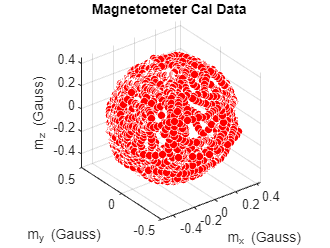

load 'heeirthanCompassdata.mat';
figure,
scatter3(Compass_Data(1,:), Compass_Data(2,:), Compass_Data(3,:), 'r', 'filled', 'MarkerEdgeColor', 'w');
title('Magnetometer Cal Data ')
axis equal
xlabel('m_x (Gauss)'); ylabel('m_y (Gauss)'); zlabel('m_z (Gauss)');

[center, radius] = LSE_sphere_fit(Compass_Data);
bias_mag = center         

bias_mag =    -0.0225
    0.0037
   -0.0337


SF_mag = radius/norm([0.0960;-0.2726;0.3790])

SF_mag = 1.0025